clear; clc;


## input file names [make sure to edit paths]


baseline_filename = '../assignment_data/baseline.nii';
followup_filename = '../assignment_data/followup.nii';
seg_filename = '../assignment_data/seg.nii';
txt_filename = '../f2b.txt';
data = load('-ascii','..\assignment_data\f2b.txt');
A = data(1:end-1,1:end-1);
b = data(1:end-1, 4);


## Test myReadNifti

[base_image, base_spacing] = myReadNifti(baseline_filename);
[follow_image, follow_spacing] = myReadNifti(followup_filename);
[seg,space_seg] = myReadNifti(seg_filename);

% We will Compare images but for the self-grade script only size
if isequal(size(base_image),[160,198,176]) && isequal(size(follow_image),[160,198,176]) 
    fprintf('myReadNifti function is working!')
else
    fprintf('Check MyReadNifti')
end

myReadNifti function is working!

## Test myWriteNifti

myWriteNifti('baseline2.nii', base_image, base_spacing)
[base2_image, base2_spacing] = myReadNifti('baseline2.nii');

if isequal(base2_image,base_image) 
    fprintf('myWriteNifti function is working!')
else
    fprintf('Check myWriteNifti')
end

myWriteNifti function is working!

## Test myViewInSNAP [change paths]

%%{
% first check using your defaults. Once confirmed, please make minor edits to make sure it runs on our system
itksnap_path = 'c:\Program Files\ITK-SNAP\bin\ITK-SNAP.exe'; % change to this itk-snap path 
temp_path = 'c:\Users\Ahmed\Documents\MATLAB\be537_hw1'; % use as path for temporary file names
myViewInSNAP(base_image, base_spacing);

ans = 0

% if you see the image appearing in ITK-SNAP
 fprintf('myViewInSNAP function is working!')

myViewInSNAP function is working!

%}

## Test myView

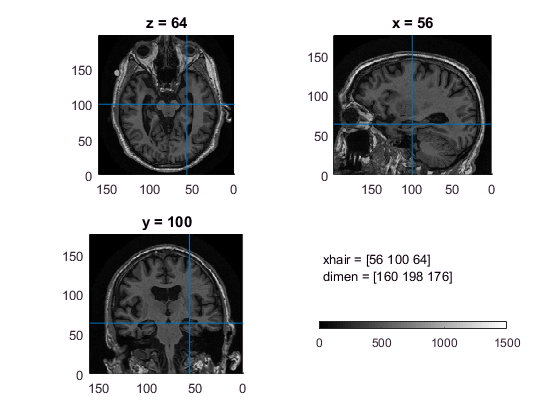

figure
myView(base_image,base_spacing) % we might change some parameters so test variations

## Test myView3D

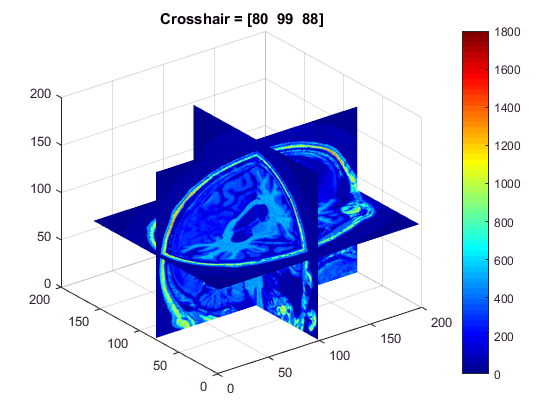

figure
myView3D(base_image, base_spacing, [80 99 88], [0 1800], 'jet')

## Test myTransformImage

moving = follow_image;
fixed = base_image;
method = [];
transform = myTransformImage(fixed,moving,A,b);

figure
myView(base_image,base_spacing)

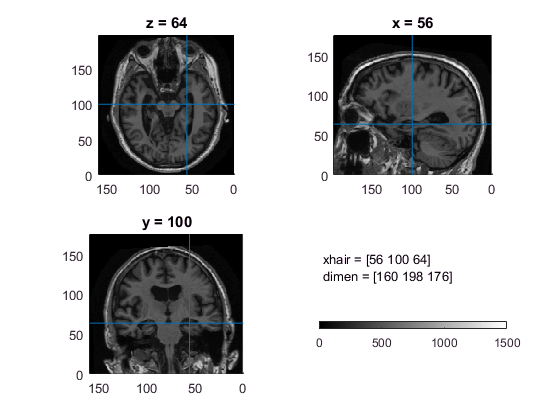

figure
myView(transform, follow_spacing)

## Test myGaussian LPF

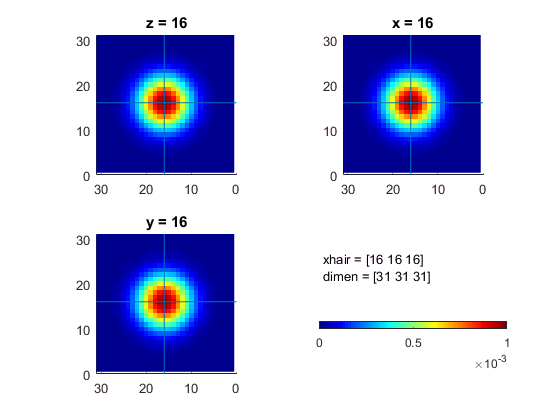

figure
delta = zeros(31,31,31);
delta(16,16,16) = 1;
delta_filtered = myGaussianLPF(delta,4);
myView(delta_filtered,[1,1,1],[16,16,16],[0 10^-3],'jet')

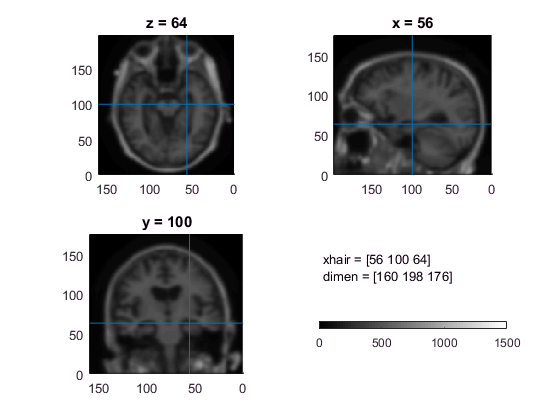


figure
base_gfilter_sigma2 = myGaussianLPF(base_image,2);
myView(base_gfilter_sigma2,base_spacing)

## Test myMeanLPF

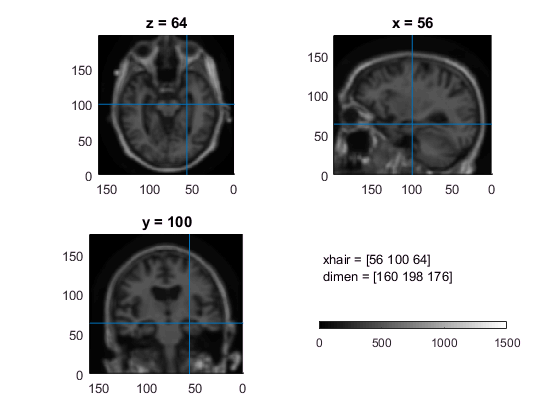

figure
base_mfilter_rad2 = myMeanLPF(base_image,2);
myView(base_mfilter_rad2,base_spacing)

## Test Difference Image [insert script name here]

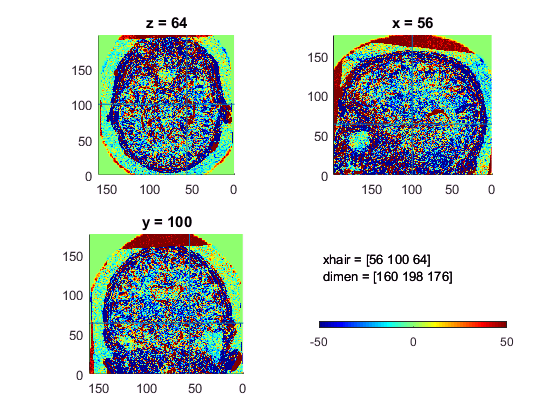

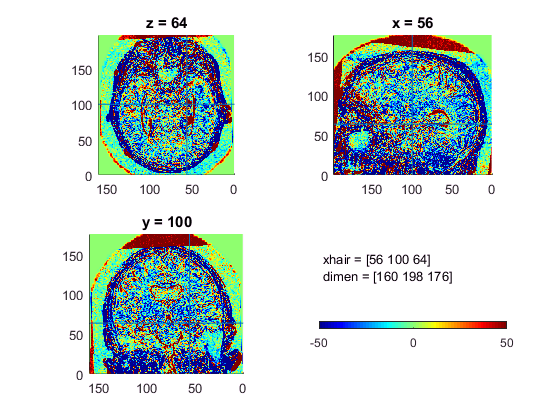

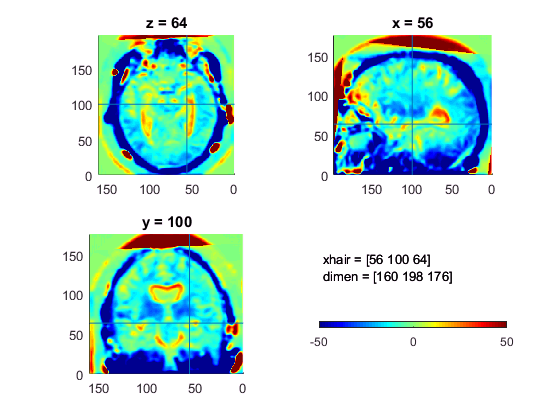

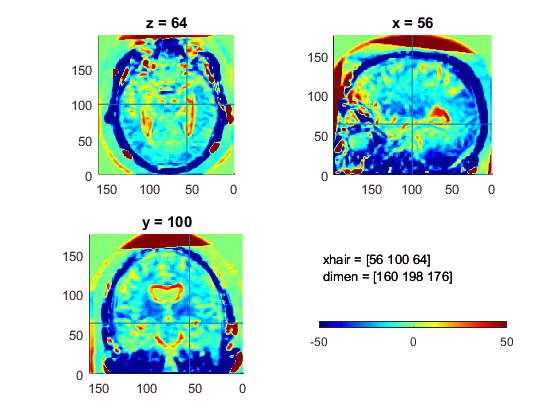

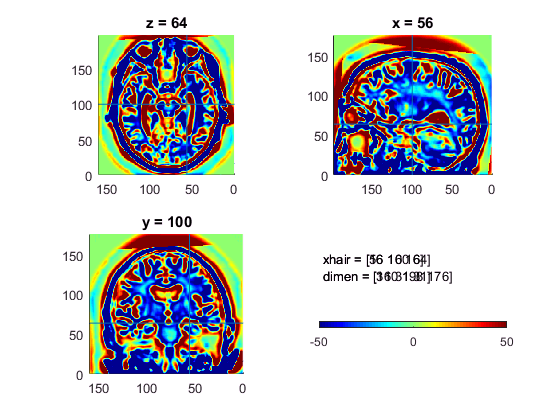

computeDiff_script %this will be the name of your script

## Test myRMSOverROI

value_base = myRMSOverROI(base_image, seg, 1);
value_follow = myRMSOverROI(follow_image,seg,1);
value_const1_base = 344.6216;
value_const1_follow = 234.9771;
if round(value_base,3) == round(value_const1_base,3) && round(value_follow,3) == round(value_const1_follow,3)
    fprintf('myRMSOverROI works!')
else 
    fprintf('Check myRMSOverROI')
end

myRMSOverROI works!

## Test Quantify intensity differences plots [insert script name for plots here]

Calculating gaussian filtering iteration 0 out of 11 
Calculating mean filtering iteration 0 out of 11 
Calculating gaussian filtering iteration 1 out of 11 
Calculating mean filtering iteration 1 out of 11 
Calculating gaussian filtering iteration 2 out of 11 
Calculating mean filtering iteration 2 out of 11 
Calculating gaussian filtering iteration 3 out of 11 
Calculating mean filtering iteration 3 out of 11 
Calculating gaussian filtering iteration 4 out of 11 
Calculating mean filtering iteration 4 out of 11 
Calculating gaussian filtering iteration 5 out of 11 
Calculating mean filtering iteration 5 out of 11 
Calculating gaussian filtering iteration 6 out of 11 
Calculating mean filtering iteration 6 out of 11 
Calculating gaussian filtering iteration 7 out of 11 
Calculating mean filtering iteration 7 out of 11 
Calculating gaussian filtering iteration 8 out of 11 
Calculating mean filtering iteration 8 out of 11 
Calculating gaussian filtering iteration 9 out of 11 
Calculatin

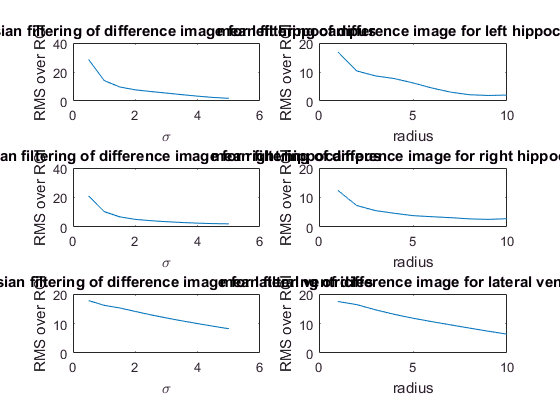

RMS_ROI_script % this will be the name of your script